# Post Calculations of Ising

## Import data to multidim array

[N_vals,T_vals,data] = importMulti('IsingResultsNew4.tsv');
%remove N=256
data(end,:,:,:)=[];
N_vals(end)=[];
T_vals(:,end)=[];

## Reweight magnetization

for i=2.270:0.005:2.280
    [N_vals,T_vals,data] = addReweightToData(N_vals,T_vals,data,i,4);
end

% boltzman_factor=@(E,newTemp,oldTemp)(exp(-65536*(1./newTemp-1/oldTemp).*E));
% 
% newMag=@(E,oldMag,newTemp,oldTemp)sum(oldMag.*boltzman_factor(E,newTemp,oldTemp))./sum(boltzman_factor(E,newTemp,oldTemp));
% 
% figure(11)
% clf
% for i=1:size(data,2)
%     nM=@(newTemp) newMag(reshape(data(4,i,1,:),[],1),reshape(data(4,i,2,:),[],1),newTemp,T_vals(i,4));
%     t=T_vals(i,4)-0.03:0.001:T_vals(i,4)+0.005;
%     plot(t,nM(t),'.')
%     hold on
% end

## Reduce data to mean and std

[O_mean,O_std,O_var,O_var_err,O_weight,O_corrLength] = ReduceObservableMulti(data);

## Plot energy

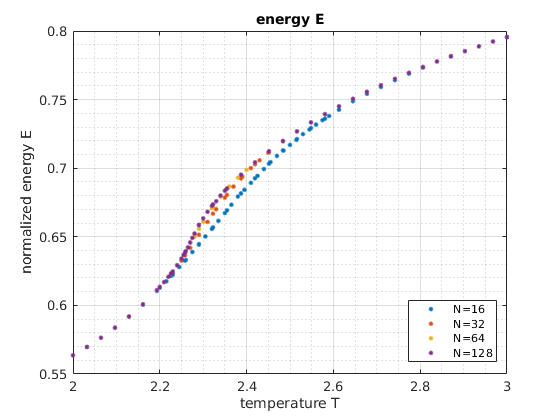

figure(1)
clf
for i=1:size(data,1)
    %errorbar(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1), ...
    %    reshape(O_std(i,:,1,:),[],1),'DisplayName',"N="+N_vals(i))
    plot(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1),'.','DisplayName',"N="+N_vals(i),'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("normalized energy E")
legend("Location","best")
title("energy E")

## Plot magnetization

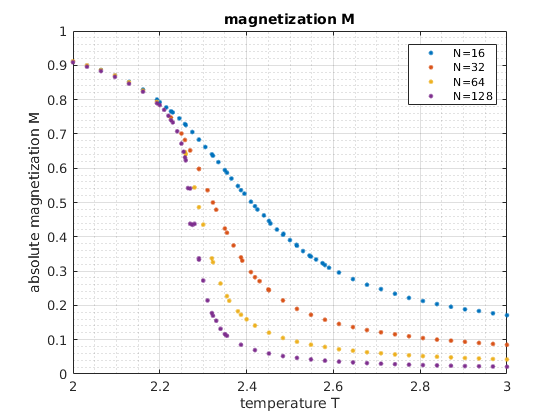

figure(2)
clf
for i=1:size(data,1)
    %errorbar(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1), ...
    %    reshape(O_std(i,:,2,:),[],1),'DisplayName',"N="+N_vals(i))
    plot(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1),'.','DisplayName',"N="+N_vals(i),'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("absolute magnetization M")
legend("Location","best")
title("magnetization M")

Fir magnetization

ft = fittype( 'fitEnergy(T,Tcrit,E0,C,beta)', 'independent', 'T');
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0.9 0 2.2 0.1];
opts.StartPoint = [0.9 0.9 2.269 0.125];
opts.Upper = [1 Inf 2.3 10];
%opts.Weights = 1./heatCap_err(:,end).^2;

% Fit model to data.
[x,y]=prepareCurveData(T_vals(:,2), reshape(O_mean(2,:,2,:),[],1));

[fitM_exponent, gof_M_exponent] = fit( x,y, ft, opts )

fitM_exponent =      General model:
     fitM_exponent(T) = fitEnergy(T,Tcrit,E0,C,beta)
     Coefficients (with 95% confidence bounds):
       C =         0.9  (fixed at bound)
       E0 =      0.1231  (0.07876, 0.1674)
       Tcrit =        2.27  (2.239, 2.301)
       beta =      0.4269  (0.1981, 0.6557)

gof_M_exponent = struct with fields:
           sse: 0.2647
       rsquare: 0.9214
           dfe: 40
    adjrsquare: 0.9174
          rmse: 0.0813


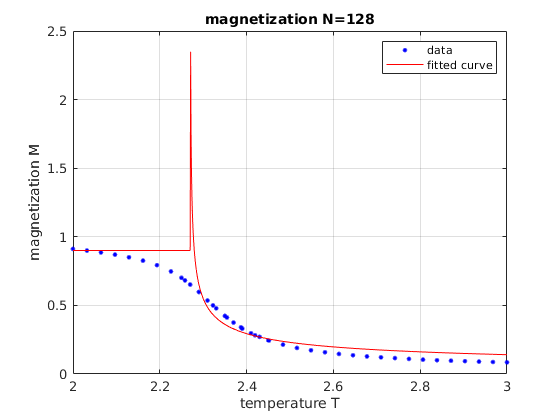


figure(3)
clf
p=plot( fitM_exponent, x,y );
p(1).MarkerSize=10;
grid on
box on
xlabel("temperature T")
ylabel("magnetization M")
title("magnetization N="+N_vals(end))

## heat capacity

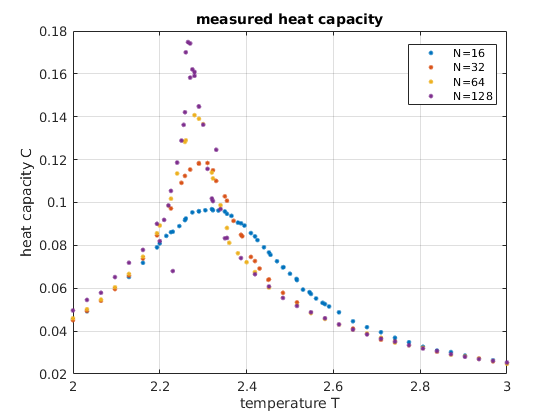

heatCap=reshape(O_var(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;
heatCap_err=reshape(O_var_err(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;

figure(4)
clf
for i=1:size(data,1)
    plot(T_vals(:,i),heatCap(:,i),'.','DisplayName',"N="+N_vals(i),'MarkerSize',10)
    hold on
end
grid on
box on
xlabel("temperature T")
ylabel("heat capacity C")
legend("Location","best")
title("measured heat capacity")

Analyse now maxima in log-log-plot and fit a linear equation to the data

ft = fittype( 'poly1' );

% Fit model to data.
[fitHeatCapMax, gof_hcm] = fit( log(N_vals)', log(max(heatCap,[],1))', ft )

fitHeatCapMax =      Linear model Poly1:
     fitHeatCapMax(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.2803  (0.245, 0.3156)
       p2 =      -3.112  (-3.249, -2.974)

gof_hcm = struct with fields:
           sse: 3.2355e-04
       rsquare: 0.9983
           dfe: 2
    adjrsquare: 0.9974
          rmse: 0.0127


Plot

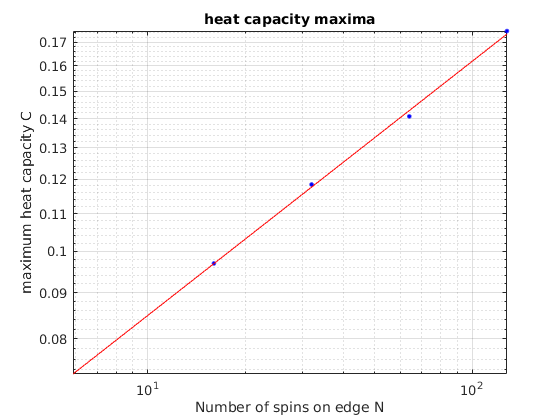

figure(3)
clf
loglog(N_vals,max(heatCap,[],1),'b.','DisplayName',"Data",'MarkerSize',10)
hold on
x=linspace(log(N_vals(1))-1,log(N_vals(end)),100);
loglog(exp(x),exp(fitHeatCapMax(x)),'-r','DisplayName',"Fit linear model")
grid on
box on
xlabel("Number of spins on edge N")
ylabel("maximum heat capacity C")
title("heat capacity maxima")

Critical exponent

fitHeatCapMax.p1

ans = 0.2803

hcap_p1_err=table(diff(confint(fitHeatCapMax))/2).Var1(1)

hcap_p1_err = 0.0353

fit exponent

ft = fittype( 'fitHeatCap(T,Tcrit,E0,gamma)', 'independent', 'T');
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 2.2 -Inf];
opts.StartPoint = [0.1 2.269 -0.5];
opts.Upper = [Inf 2.3 Inf];
%opts.Weights = 1./heatCap_err(:,end).^2;

% Fit model to data.
[x,y]=prepareCurveData(T_vals(:,end), heatCap(:,end));

[fitHC_exponent, gof_hc_exponent] = fit( x,y, ft, opts )

fitHC_exponent =      General model:
     fitHC_exponent(T) = fitHeatCap(T,Tcrit,E0,gamma)
     Coefficients (with 95% confidence bounds):
       E0 =     0.04161  (0.03603, 0.04719)
       Tcrit =       2.267  (2.266, 2.268)
       gamma =     -0.2639  (-0.2956, -0.2321)

gof_hc_exponent = struct with fields:
           sse: 0.0163
       rsquare: 0.8571
           dfe: 50
    adjrsquare: 0.8514
          rmse: 0.0180



figure(4)
clf
p=plot( fitHC_exponent, T_vals(:,end), heatCap(:,end) );

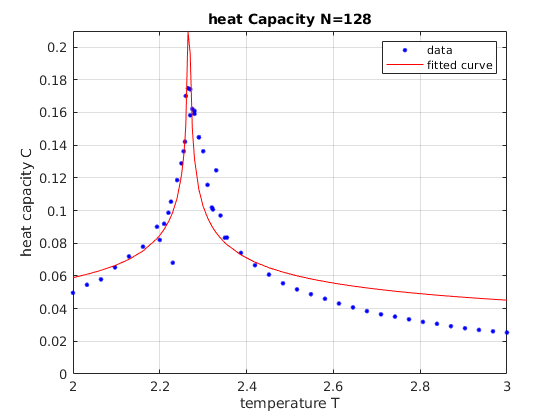

p(1).MarkerSize=10;
grid on
box on
xlabel("temperature T")
ylabel("heat capacity C")
ylim([0,1.2*max(heatCap(:,end))])
title("heat Capacity N="+N_vals(end))

## susceptibility

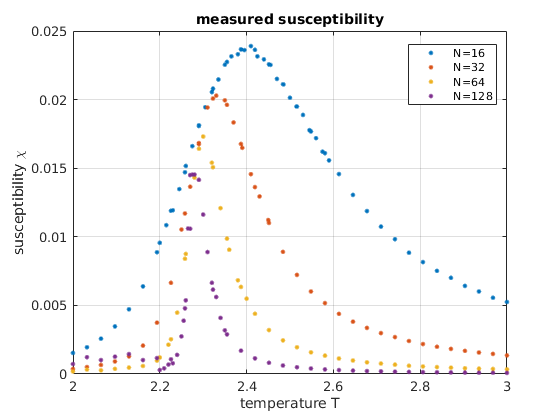

suscept=reshape(O_var(:,:,2),length(N_vals),[])'./T_vals;
suscept_err=reshape(O_var_err(:,:,2),length(N_vals),[])'./T_vals;

figure(5)
clf
for i=1:size(data,1)
    plot(T_vals(:,i),suscept(:,i),'.','DisplayName',"N="+N_vals(i),'MarkerSize',10)
    hold on
end
grid on
box on
xlabel("temperature T")
ylabel("susceptibility \chi")
legend("Location","best")
title("measured susceptibility")

Analyse now maxima in log-log-plot and fit a linear equation to the data

ft = fittype( 'poly1' );

% Fit model to data.
[fitSusceptMax, gof_susc] = fit( log(N_vals)', log(max(suscept,[],1))', ft )

fitSusceptMax =      Linear model Poly1:
     fitSusceptMax(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.2381  (-0.2517, -0.2245)
       p2 =      -3.072  (-3.125, -3.019)

gof_susc = struct with fields:
           sse: 4.8199e-05
       rsquare: 0.9996
           dfe: 2
    adjrsquare: 0.9995
          rmse: 0.0049


Plot

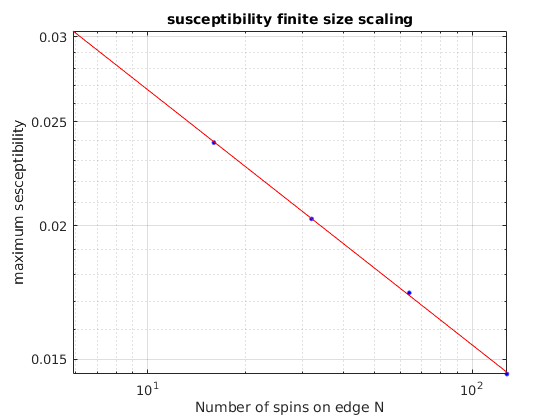

figure(6)
clf
loglog(N_vals,max(suscept,[],1),'b.','DisplayName',"Data",'MarkerSize',10)
hold on
x=linspace(log(N_vals(1))-1,log(N_vals(end)),100);
loglog(exp(x),exp(fitSusceptMax(x)),'-r','DisplayName',"Fit linear model")
grid on
box on
xlabel("Number of spins on edge N")
ylabel("maximum sesceptibility")
title("susceptibility finite size scaling")

Critical exponent

fitSusceptMax.p1

ans = -0.2381

suscept_p1_err=table(diff(confint(fitSusceptMax))/2).Var1(1)

suscept_p1_err = 0.0136

fit exponent

figure(7)
clf

ft = fittype( 'fitHeatCap(T,Tcrit,E0,-gamma)', 'independent', 'T');
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [1E-5 2.2 0];
opts.StartPoint = [0.1 2.269 -1];
opts.Upper = [Inf 2.3 2];
%opts.Weights = 1./suscept_err(:,end).^2;

% Fit model to data.
[x,y]=prepareCurveData(T_vals(:,end), suscept(:,end));

[fitSusc_exponent, gof_susc_exponent] = fit( x,y, ft, opts )

fitSusc_exponent =      General model:
     fitSusc_exponent(T) = fitHeatCap(T,Tcrit,E0,-gamma)
     Coefficients (with 95% confidence bounds):
       E0 =    0.000895  (0.0004006, 0.001389)
       Tcrit =       2.273  (2.272, 2.274)
       gamma =      0.4797  (0.3693, 0.59)

gof_susc_exponent = struct with fields:
           sse: 3.8728e-04
       rsquare: 0.6825
           dfe: 50
    adjrsquare: 0.6698
          rmse: 0.0028


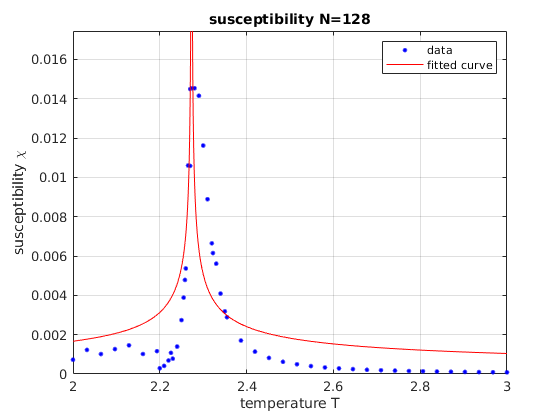



p=plot( fitSusc_exponent, x,y );
p(1).MarkerSize=10;
grid on
box on
%set(gca,'YScale','log')
xlabel("temperature T")
ylabel("susceptibility \chi")
ylim([0,1.2*max(suscept(:,end))])
title("susceptibility N="+N_vals(end))

exponent is:

fitSusc_exponent.gamma

ans = 0.4797

suscept_gamma_err=table(diff(confint(fitSusc_exponent))/2).Var1(3)

suscept_gamma_err = 0.1104

## Binder Cumulants

figure(8)
clf
U_L=(1-mean(data(:,:,2,:).^4,4)./3./mean(data(:,:,2,:).^2,4).^2)';

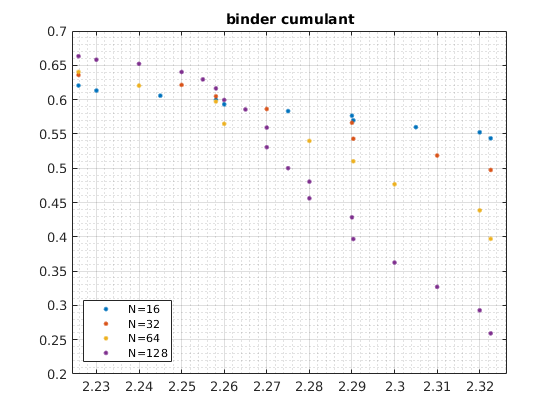

% Smooth input data
U_LSmoothed = smoothdata(U_L,"sgolay","SmoothingFactor",0.35,"Degree",3);

clf
for i=1:size(data,1)
    plot(T_vals(:,i),U_LSmoothed(:,i),'.','DisplayName',"N="+N_vals(i),'MarkerSize',10  );  
    hold on
end
box on
grid on
grid minor
legend("Location","best")
title("binder cumulant")

xlim([2.2245 2.3264])

%ylim([0.534 0.666])